clc
clear all
close all

filename = "caravan_48khz.wav";
[x, Fs] = audioread(filename);

**2.1 STFT analysis**

1/ DFT of Hann Window

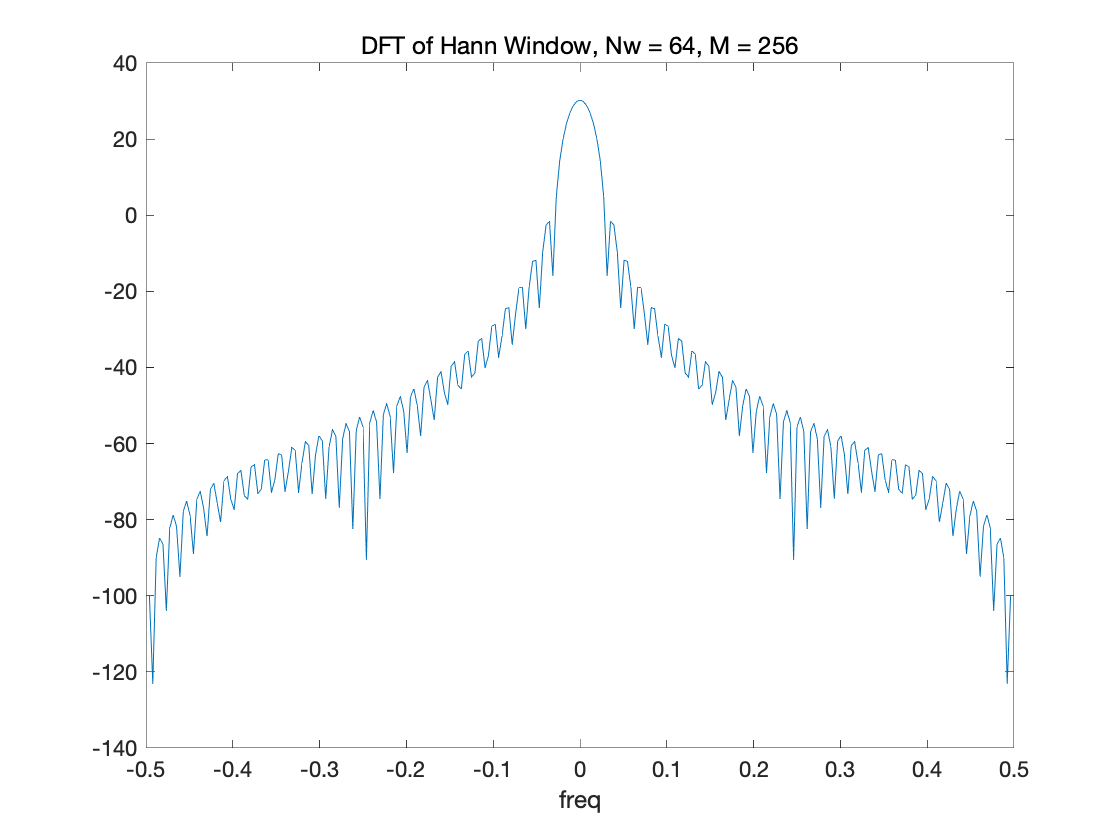

Nw = 64; % length of Hann Window
M = 256; % order of DFT
w = hanning(Nw);
Wf = 20*log10(abs(fftshift(fft(w,M))));
freq = [-0.5:1/M:0.5-1/M]';
figure("Name","DFT of Hann Window");
plot(freq,Wf);
figure_titel = "DFT of Hann Window, Nw = " + Nw + ", M = " + M;
title(figure_titel);
xlabel("freq");

2/ Fix $\lambda$ in expression(1)

$Wx(\lambda , b) =\sum_{n \in \mathbb{Z}} x(n)w(n - b)e^{ -j2\pi \lambda n} ,$ which can be combined as $Wx(\lambda , b) =\sum_{n \in \mathbb{Z}} x(n)\left(w(n - b)e^{ -j2\pi \lambda n}\right)$. Therefore, the term $w(n - b)e^{ -j2\pi \lambda n}$ is a filter. If $w(n)$ is a low-pass filter, then $w(n-b)$ is shifted by $b$, which is a band-pass filter. If the window $w(n)$ is even, then $w(n - b)$ will also be even, making it a Type 1 FIR filter. If the window $w(n)$ is odd, then $w(n - b)$ will also be odd, making it a Type 3 FIR filter.

3/ band-pass convention

$\tilde{X}(\lambda,b) = W_x(\lambda,b) e^{j2\pi \lambda b}$, and the stft.m implement the "band-pass convention".

4/ 

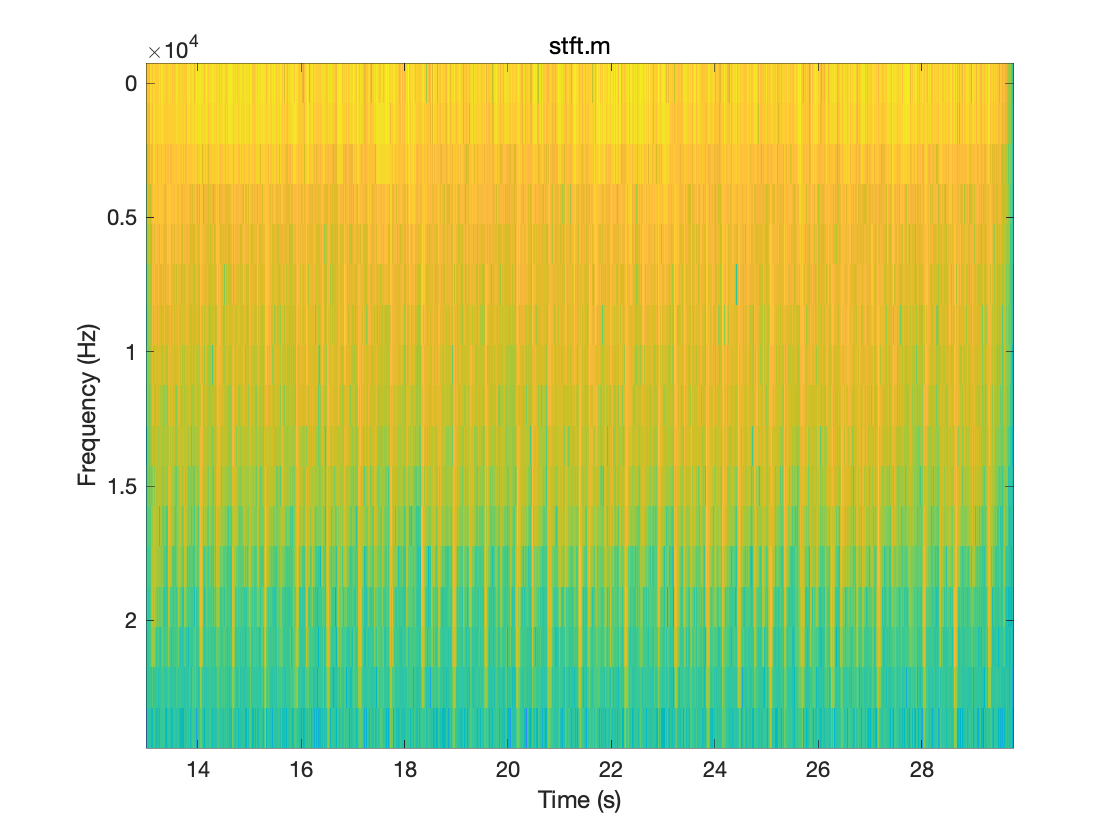

M = 32;
R = 1;
k = 3;

% use stft.m
N = length(x);
Nw = 26;
w = hanning(Nw);
L = M/2 + 1;

Nt = fix( (N-Nw)/R ); % calcul du nombre de tfd � calculer
y = zeros(N,1); % signal de synth�se
for u=1:Nt;  % boucle sur les trames
   deb = (u-1)*R +1; % d�but de trame
   fin = deb + Nw -1; % fin de trame
   tx = x(deb:fin).*w; % calcul de la trame  
   X = fft(tx,M); % tfd � l'instant b
   
   Xtilde(:,u)=X;
   
   % op�rations de transformation (sur la partie \nu > 0)
   % ....
   Y = X;
   % fin des op�ration de transformation
   
   % resynth�se
   % overlap add
end

freq = (0:M/2)/M*Fs;
b = [0:Nt-1]*R/Fs+Nw/2;
imagesc(b,freq,db(abs(Xtilde(1:L,:))));
title('stft.m')
xlabel('Time (s)');
ylabel('Frequency (Hz)');

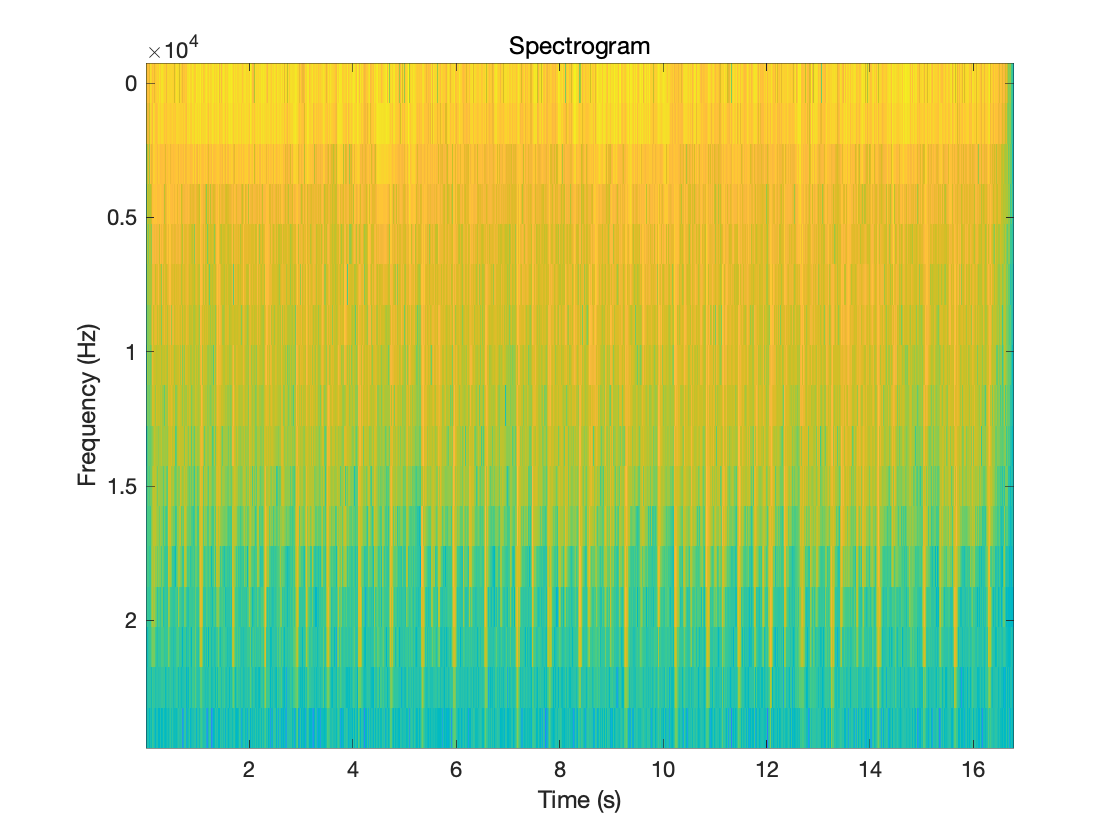

% use spectrogram
[S, F, T] = spectrogram(x, hann(M), M-R, M, Fs);
x_k_u = S(4, :);
figure;
imagesc(T, F, 10 * log10(abs(S)));
title('Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

$x_3(u)$ is complex.

**2.2 Reconstruction**

5/ 

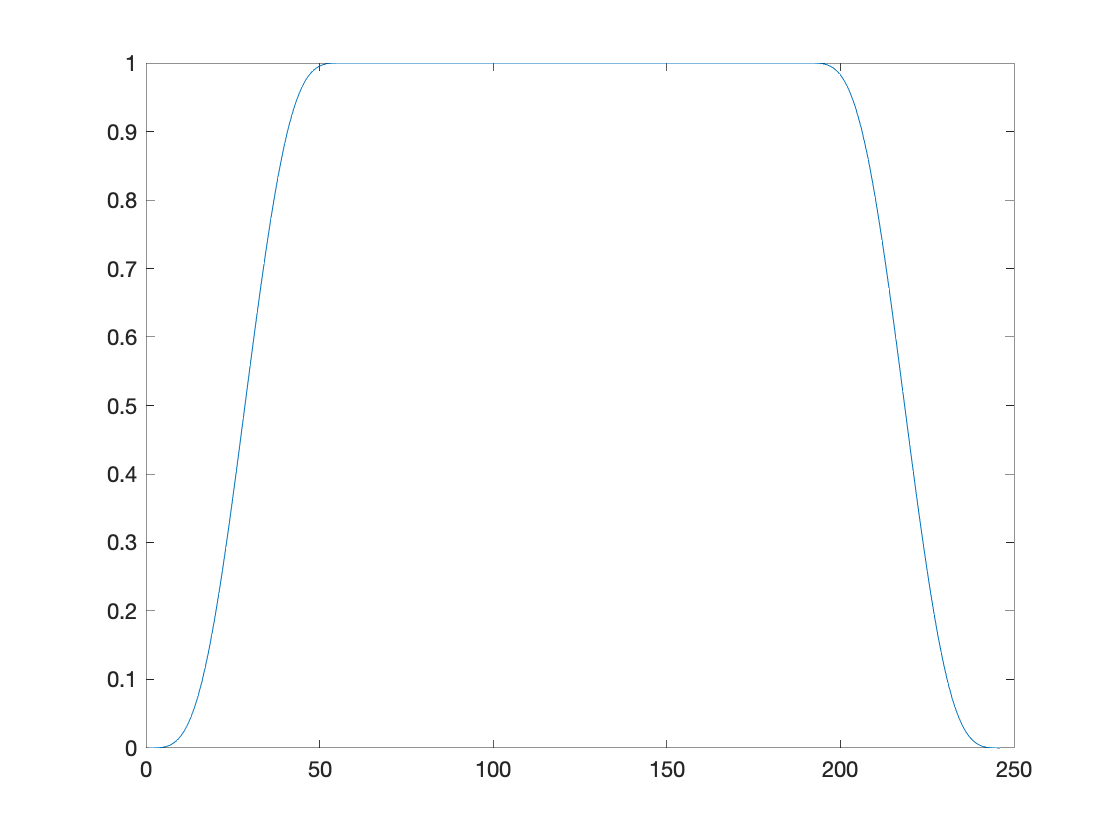

Nw = 75;
w = hanning(Nw);

wp = w.*w; % h(n)^2
% wp = wp
y = ola(wp,int16(Nw/4));
y = y/max(y);
figure("Name","overlap h(n)^2");
plot(y);

6/ 

N = length(x); % longueur du signal
Nw = 32;
w = hanning(Nw); % d�finition de la fenetre d'analyse
% ws = w; % d�finition de la fen�tre de synth�se
R = Nw/4; % incr�ment sur les temps d'analyse,
          % appel� hop size, t_a=uR
M = 32; % ordre de la tfd
L = M/2+1;

Nt = fix( (N-Nw)/R ); % calcul du nombre de tfd � calculer
y = zeros(N,1); % signal de synth�se

for u=1:Nt  % boucle sur les trames
   deb = (u-1)*R +1; % d�but de trame
   fin = deb + Nw -1; % fin de trame
   tx = x(deb:fin).*w; % calcul de la trame  
   X = fft(tx,M); % tfd � l'instant b
   % reconstruite
   invY = ifft(X,Nw);
   ty = invY .* w;
   y(deb:fin) = real(y(deb:fin)) + real(ty);

end

2.3 STFT audio equalizer

7/

N = length(x); % longueur du signal
Nw = 32;
w = hanning(Nw); % d�finition de la fenetre d'analyse
R = Nw/4; % incr�ment sur les temps d'analyse,
          % appel� hop size, t_a=uR
M = 32; % ordre de la tfd
L = M/2+1;

wk = ones(M,1);
wk(1:int16(L/2)) = 1.5;
wk(int16(L/2)+1:L) = 0.1;
wk(L+1:M-int16(L/2)) = 0.1;
wk(M-int16(L/2)+1:M) = 1.5;

Nt = fix( (N-Nw)/R ); % calcul du nombre de tfd � calculer
y = zeros(N,1); % signal de synth�se

for u=1:Nt  % boucle sur les trames
   deb = (u-1)*R +1; % d�but de trame
   fin = deb + Nw -1; % fin de trame
   tx = x(deb:fin).*w; % calcul de la trame  
   X = fft(tx,M); % tfd � l'instant b
   Xeq = X.*wk;
   % reconstruite
   invY = ifft(Xeq,Nw);
   ty = invY .* w;
   y(deb:fin) = real(y(deb:fin)) + real(ty);

end
